# Walking Robot: Inverse Kinematics with Symbolic Math Toolbox

## Sit-to-stand case

### Define and solve symbolic equations

% syms x y L1 L2 theta1 theta2 real
syms L1 L2 L3 L4 h1 l1 l2 l3 l4 m1 m2 m3 m4 real positive
syms COM_x COM_y theta1 theta2 theta3 theta4 x1 x2 x3 x4 y1 y2 y3 y4 real
t1 = theta1;
t11 = t1 + pi/2;
t2 = t11 + theta2;
t3 = t2 + theta3;
t4 = t3 + theta4;

### Find all geometric angles

warning off

% solve theta1
theta1eqx = x1 == L1*cos(t1);
theta1eqy = y1 == L1*sin(t1);
sol1 = solve(theta1eqy, ...
    theta1,'Real',true,"IgnoreAnalyticConstraints",true);
t1sol = simplify(sol1(1), ...
    "All",true,"Criterion","preferReal");

% solve theta2
theta2eqx = x2 == rhs(theta1eqx) + h1*cos(t11) + L2*cos(t2);
theta2eqy = y2 == rhs(theta1eqy) + h1*sin(t11) + L2*sin(t2);
sol2 = solve(subs(theta2eqy, t1, t1sol), ...
    theta2,'Real',true,"IgnoreAnalyticConstraints",true);
t2sol = simplify(sol2(1),"Criterion","preferReal");

% solve theta3
theta3eqx = x3 == rhs(theta2eqx) + L3*cos(t3);
theta3eqy = y3 == rhs(theta2eqy) + L3*sin(t3);
sol3 = solve(subs(theta3eqy, [theta1 theta2], [t1sol t2sol]), ...
    theta3,'Real',true,"IgnoreAnalyticConstraints",true);
t3sol = simplify(sol3(1),"Criterion","preferReal");

% solve theta4
theta4eqx = x4 == rhs(theta3eqx) + L4*cos(t4);
theta4eqy = y4 == rhs(theta3eqy) + L4*sin(t4);
sol4 = solve(subs(theta4eqy, [theta1 theta2 theta3], [t1sol t2sol t3sol]), ...
    theta4,'Real',true,"IgnoreAnalyticConstraints",true);
t4sol = simplify(sol4(1),"Criterion","preferReal");

x1m = simplify(subs(rhs(theta1eqx), L1, l1));
y1m = simplify(subs(rhs(theta1eqy), L1, l1));
x2m = simplify(subs(rhs(theta2eqx), L2, l2));
y2m = simplify(subs(rhs(theta2eqy), L2, l2));
x3m = simplify(subs(rhs(theta3eqx), L3, l3));
y3m = simplify(subs(rhs(theta3eqy), L3, l3));
x4m = simplify(subs(rhs(theta4eqx), L4, l4));
y4m = simplify(subs(rhs(theta4eqy), L4, l4));

Mtotal = m1 + m2 + m3 + m4;

COMxeq = simplify(1/Mtotal*(m1*x1m + m2*x2m + m3*x3m + m4*x4m), ...
    "Criterion","preferReal","Steps",50);
COMyeq = simplify(1/Mtotal*(m1*y1m + m2*y2m + m3*y3m + m4*y4m), ...
    "Criterion","preferReal","Steps",50);

warning on

### Solution evaluation

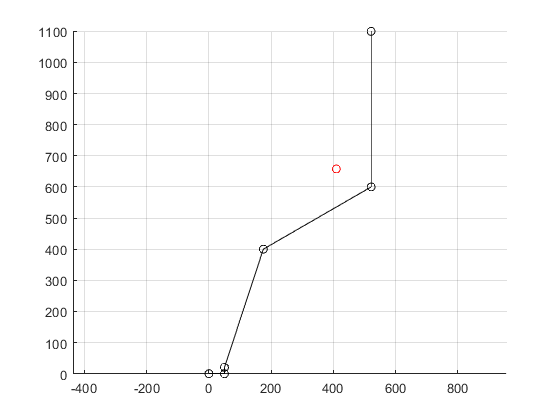

clf, close all

% example center of mass of each joint
subsVars = {L1 L2 L3 L4 h1 ...
    x1 x2 x3 x4 ... % COMx of each joint
    y1 y2 y3 y4 ... % COMy of each joint
    m1 m2 m3 m4 ...
    l1 l2 l3 l4};
subsValues = {50 400 400 500 20 ...
    10 50 150 20 ...
    0 400 600 1100 ...
    1 5 6 20 ...
    25 200 200 250};

theta1n = double(subs(t1sol, subsVars, subsValues));
theta2n = double(subs(t2sol, subsVars, subsValues));
theta3n = double(subs(t3sol, subsVars, subsValues));
theta4n = double(subs(t4sol, subsVars, subsValues));
% thetas = [theta1n theta2n theta3n theta4n];

% example exoskeleton parameters
subsVars2 = {L1 L2 L3 L4 h1 ...
    l1 l2 l3 l4 ...
    m1 m2 m3 m4 ...
    theta1 theta2 theta3 theta4};
subsValues2 = {50 400 400 500 20 ...
    25 200 200 250 ...
    1 5 6 20 ...
    theta1n theta2n theta3n theta4n};

hold on
plot([0 ...
    double(subs(rhs(theta1eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta1eqx) + h1*cos(t11), subsVars2, subsValues2)) ...
    double(subs(rhs(theta2eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta3eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta4eqx), subsVars2, subsValues2))], ...
    [0 ...
    double(subs(rhs(theta1eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta1eqy) + h1*sin(t11), subsVars2, subsValues2)) ...
    double(subs(rhs(theta2eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta3eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta4eqy), subsVars2, subsValues2))], 'ko-')
plot(double(subs(COMxeq, subsVars2, subsValues2)), ...
    double(subs(COMyeq, subsVars2, subsValues2)), 'ro')
axis equal, grid on, hold off

### Save solution to a MATLAB Function

thetasn = matlabFunction([t1sol t2sol t3sol t4sol],'File','Tests\JointInvKin');
COM = matlabFunction([COMxeq COMyeq],'File','Tests\JointCOMTraj',...
    'Outputs',{'COM_est'});

Notice that there can be two solutions for the same position. We can process this by choosing an answer that makes physical sense -- for example, the knee is not allowed to bend backwards. Idea: path generation with initial and ending boundary. The body moves such that the least amount of energy (kinetic + potential energy) is used.

## Joint trajectory polynomial fit

### Define and solve symbolic equations

syms theta(t)
syms t_f t real positive
syms a b c d e f real
syms theta_i theta__dot_i theta__ddot_i real
syms theta_f theta__dot_f theta__ddot_f real
assume(t<=t_f)

### Polynomial fit solution

We propose that all joint angle trajectories can be approximated by a 5th degree polynomial in time $t$ represented by equation:


$$\theta \left(t\right)=at^5 +bt^4 +ct^3 +dt^2 +et+f$$


fun = theta == a*t^5 + b*t^4 + c*t^3 + d*t^2 + e*t + f;
% initial posture at t = 0
fi0 = subs(fun,t,0);
% initial posture at t = tf
ff0 = subs(fun,t,t_f);
% 1st derivative at t = 0
fi1 = subs(diff(fun,t),t,0);
% 1st derivative at t = tf
ff1 = subs(diff(fun,t),t,t_f);
% 2nd derivative at t = 0
fi2 = subs(diff(fun,t,2),t,0);
% % 2nd derivative at t = tf
% ff2 = subs(diff(fun,t,2),diff(theta,t,2),diff(theta_f,t,2));
% ff2 = subs(ff2,t,t_f);

warning off

res = solve([fi0 fi1 fi2 ff0 ff1],[b c d e f],...
    'Real',true,'IgnoreAnalyticConstraints',true);

warning on

%simplify the solutions
bsol = simplify(res.b,"Criterion","preferReal","Steps",50);
csol = simplify(res.c,"Criterion","preferReal","Steps",50);
dsol = simplify(res.d,"Criterion","preferReal","Steps",50);
esol = simplify(res.e,"Criterion","preferReal","Steps",50);
fsol = simplify(res.f,"Criterion","preferReal","Steps",50);

% assign variables for substitution
thetas = [diff(theta,t,2) diff(theta) theta];
subThetas = [theta__ddot_i theta__dot_i theta_i...
    theta__ddot_f theta__dot_f theta_f];

% substitute variables into the solutions
bsol = subs(bsol,[thetas(0) thetas(t_f)],subThetas);
csol = subs(csol,[thetas(0) thetas(t_f)],subThetas);
dsol = subs(dsol,[thetas(0) thetas(t_f)],subThetas);
esol = subs(esol,[thetas(0) thetas(t_f)],subThetas);
fsol = subs(fsol,[thetas(0) thetas(t_f)],subThetas);

jointTraj = simplify(subs(rhs(fun),[b c d e f],[bsol csol dsol esol fsol]));

### Save solution to a MATLAB Function

JointTrajFit = matlabFunction(jointTraj,'File','Tests\JointTrajFit',...
    'Outputs',{'theta'});